# Experiment 6.1

## Name: Timothy Roche

## Objectives

To verify the effect of pole location upon stability. To verify the effect upon stability of loop gain in a negative feedback system.   

### Minimum Required Software Packages

MATLAB, Simulink, and the Control System Toolbox.

## Prelab

### Problem 1

*Find the equivalent transfer function of the negative feedback system of Figure P6.19 below if *$G(s) = \frac{K}{s(s+2)^2}$ and $H(s) = 1$.

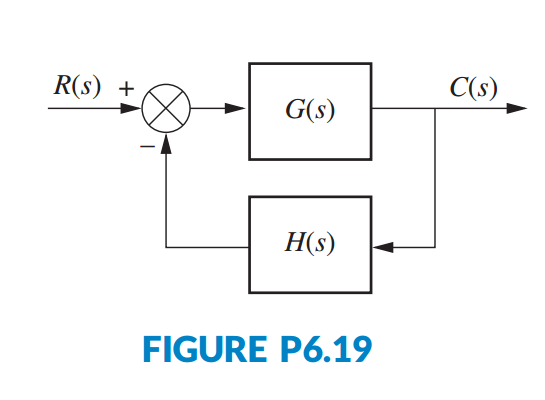

**Answer:**

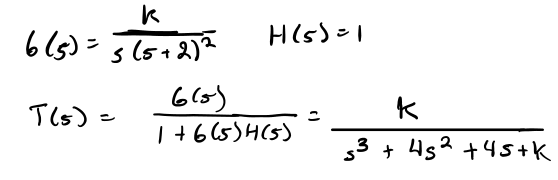

### Problem 2

*For the system of Prelab Problem 1, find two values of gain that will yield closed-loop, overdamped, second-order poles. Repeat this for two gains which will produce underdamped poles.*

**Answer:**

**Overdamped:**


$$k = 1$$


*Verified by slider, then confirmed on root locus.*

fc = 1

fc = 1

k_vals = 1

k_vals = 1

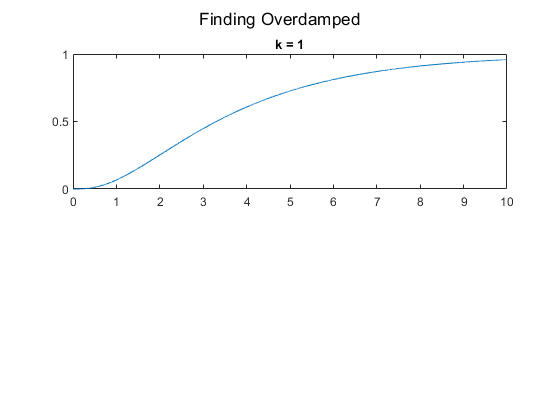

fc=fc+1; figure(fc);
for it=1:length(k_vals)
    k = k_vals(it);
    subplot(2,1,it);
    simOut = sim('ex6.slx','ReturnWorkspaceOutputs','on');
    plot(simOut.question.Time, simOut.question.Data);
    title("k = "+k);
end 
sgtitle("Finding Overdamped")

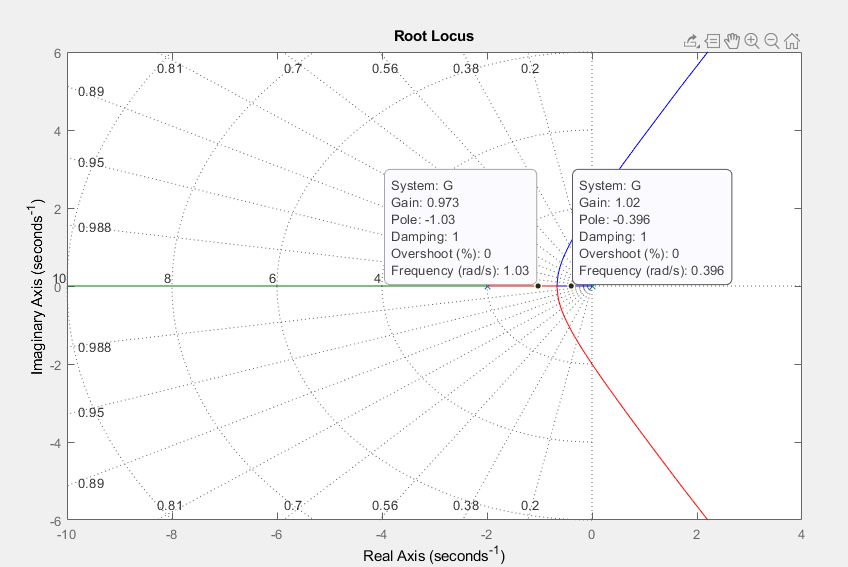


$$k = 0.8$$


*Verified by slider, then confirmed on root locus*

k_vals = 0.8

k_vals = 0.8000

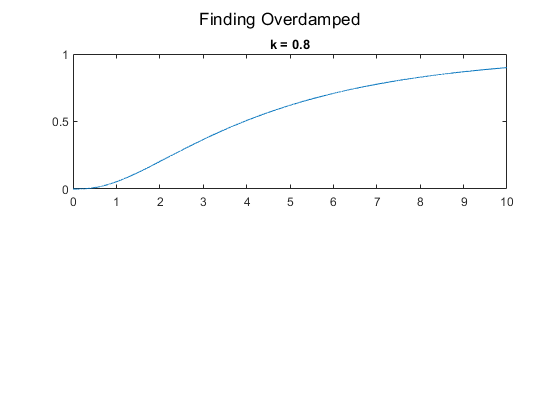

fc=fc+1; figure(fc);
for it=1:length(k_vals)
    k = k_vals(it);
    subplot(2,1,it);
    simOut = sim('ex6.slx','ReturnWorkspaceOutputs','on');
    plot(simOut.question.Time, simOut.question.Data);
    title("k = "+k);
end 
sgtitle("Finding Overdamped")

*.*

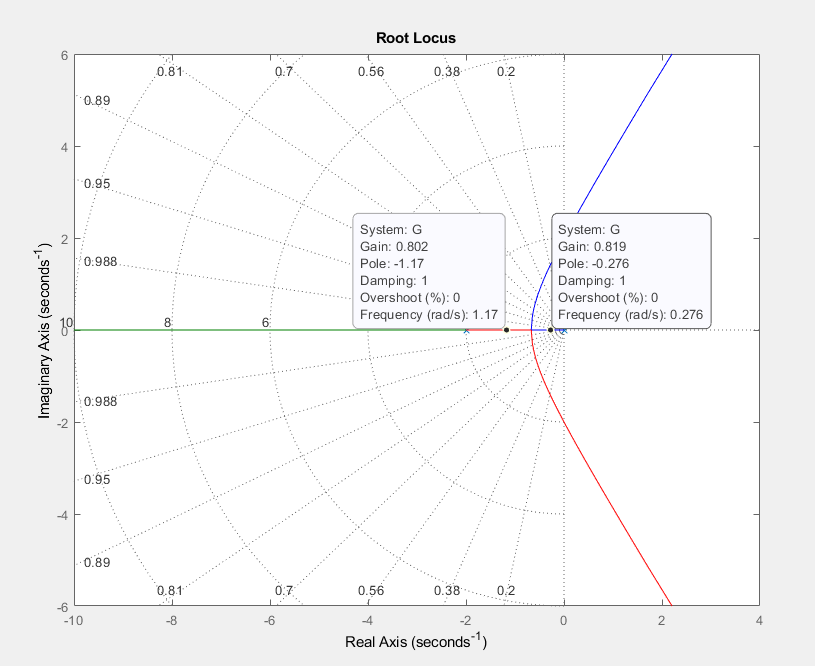

**Underdamped:**


$$k = 3$$


*Verified by slider, then confirmed on root locus.*

k_vals = 3

k_vals = 3

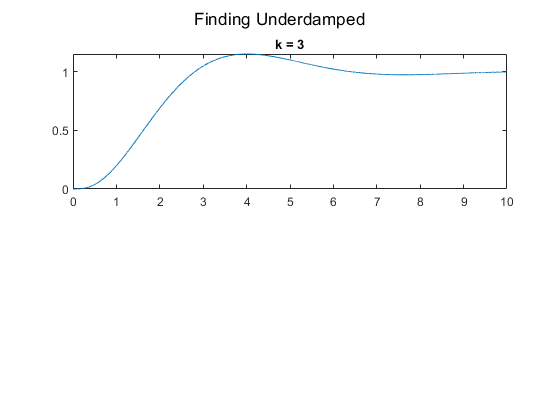

fc=fc+1; figure(fc);
for it=1:length(k_vals)
    k = k_vals(it);
    subplot(2,1,it);
    simOut = sim('ex6.slx','ReturnWorkspaceOutputs','on');
    plot(simOut.question.Time, simOut.question.Data);
    title("k = "+k);
end 
sgtitle("Finding Underdamped")

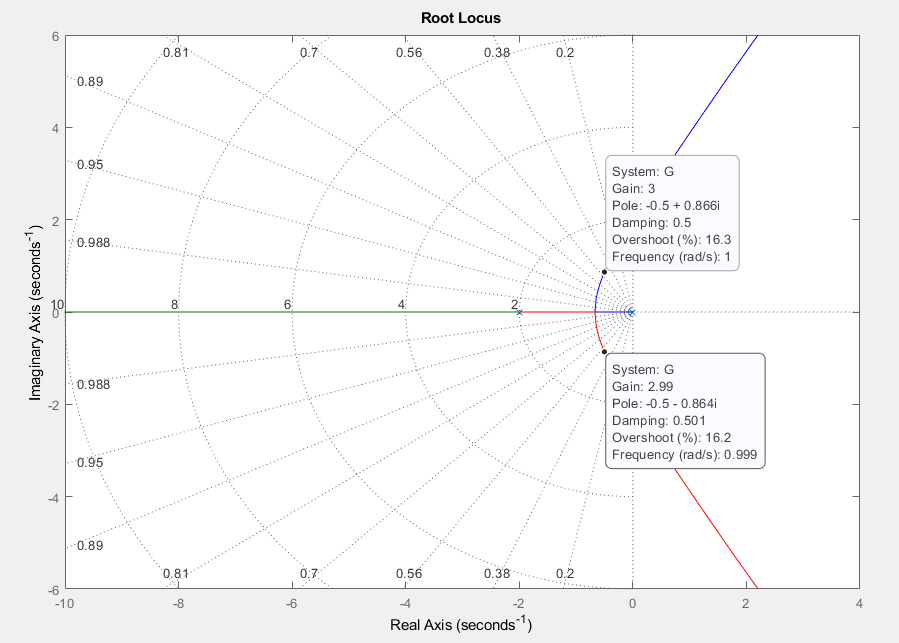


$$k = 5$$


*Verified by slider, then confirmed on root locus.*

k_vals = 5

k_vals = 5

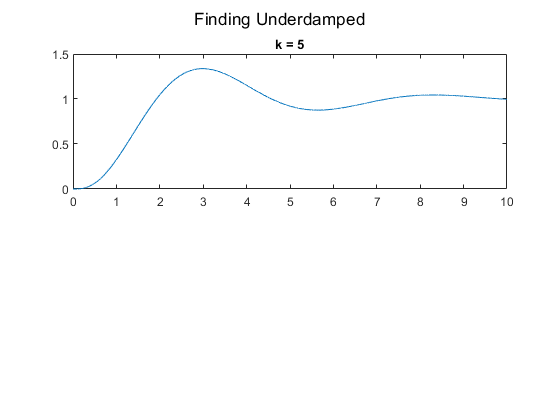

fc=fc+1; figure(fc);
for it=1:length(k_vals)
    k = k_vals(it);
    subplot(2,1,it);
    simOut = sim('ex6.slx','ReturnWorkspaceOutputs','on');
    plot(simOut.question.Time, simOut.question.Data);
    title("k = "+k);
end 
sgtitle("Finding Underdamped")

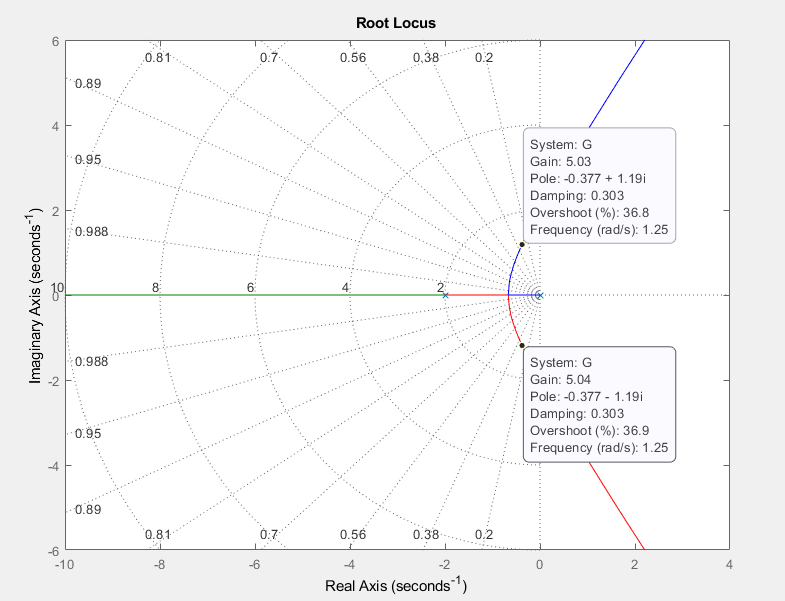

### Problem 3

*For the system in Prelab Problem 1, find the value of gain, *$K$*, that will make the system critcally damped.*

**Answer:**


$$k = 1.9$$


*Verified by slider, then confirmed on root locus.*

k_vals = 1.19

k_vals = 1.1900

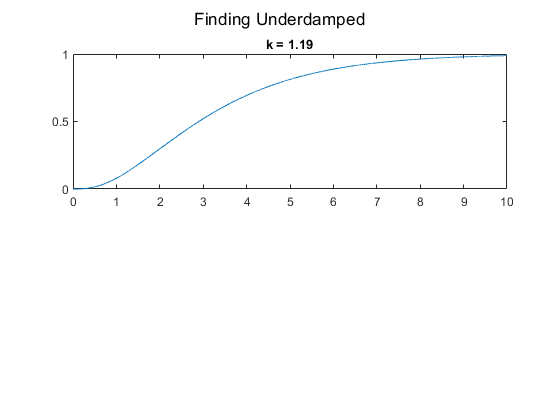

fc=fc+1; figure(fc);
for it=1:length(k_vals)
    k = k_vals(it);
    subplot(2,1,it);
    simOut = sim('ex6.slx','ReturnWorkspaceOutputs','on');
    plot(simOut.question.Time, simOut.question.Data);
    title("k = "+k);
end 
sgtitle("Finding Underdamped")

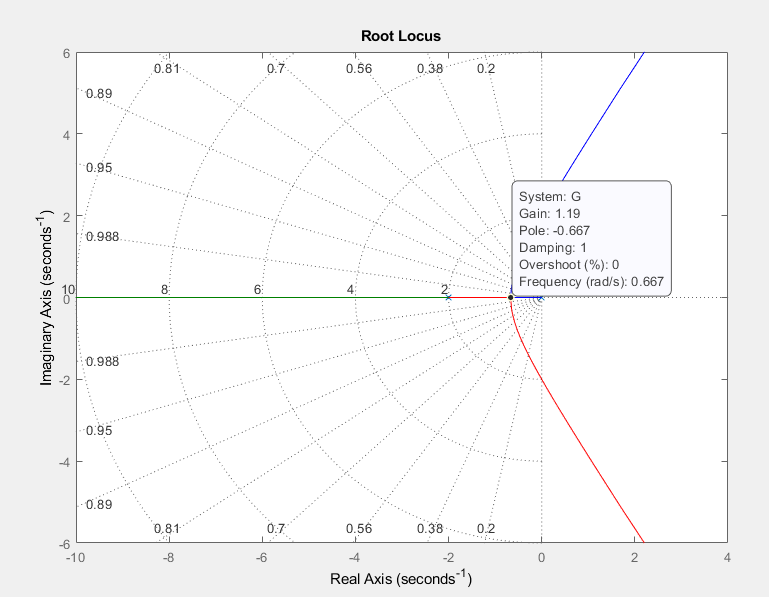

### Problem 4

*For the system of Prelab Problem 1, find the value of gain, *$K$, *that will make the system marginally stable. Also, find the frequency of oscialltion at that value of *$K$*that makes the system marginally stable.*

**Answer:**


$$k = 16$$


*Verified by slider, confirmed on Ruth Table, then confirmed on root locus.*

k_vals = 16

k_vals = 16

fc=fc+1; figure(fc);
for it=1:length(k_vals)
    k = k_vals(it);
    subplot(2,1,it);
    simOut = sim('ex6.slx','ReturnWorkspaceOutputs','on');
    plot(simOut.question.Time, simOut.question.Data);
    stepinfo(simOut.question.Data, simOut.question.Time)
    title("k = "+k);
end 

ans = struct with fields:
        RiseTime: 0.3212
    SettlingTime: 9.9710
     SettlingMin: 0.1056
     SettlingMax: 1.8944
       Overshoot: 514.3649
      Undershoot: 0
            Peak: 1.8944
        PeakTime: 8.0860


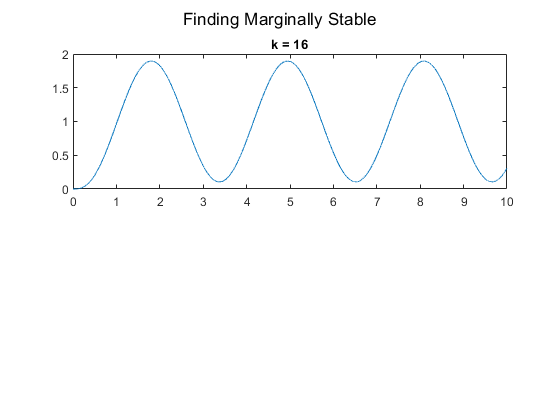

sgtitle("Finding Marginally Stable")

**Finding Gain K for Marginal Stability using Ruth Table**

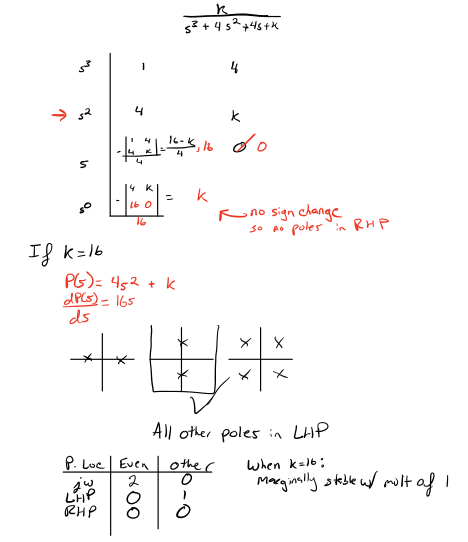

**Using the result from the Ruth Table, **$\omega_d$** can be found**

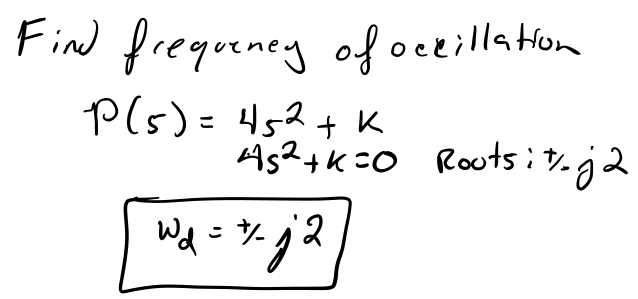

**Verifying Gain for Marginal Stability Using Root Locus**

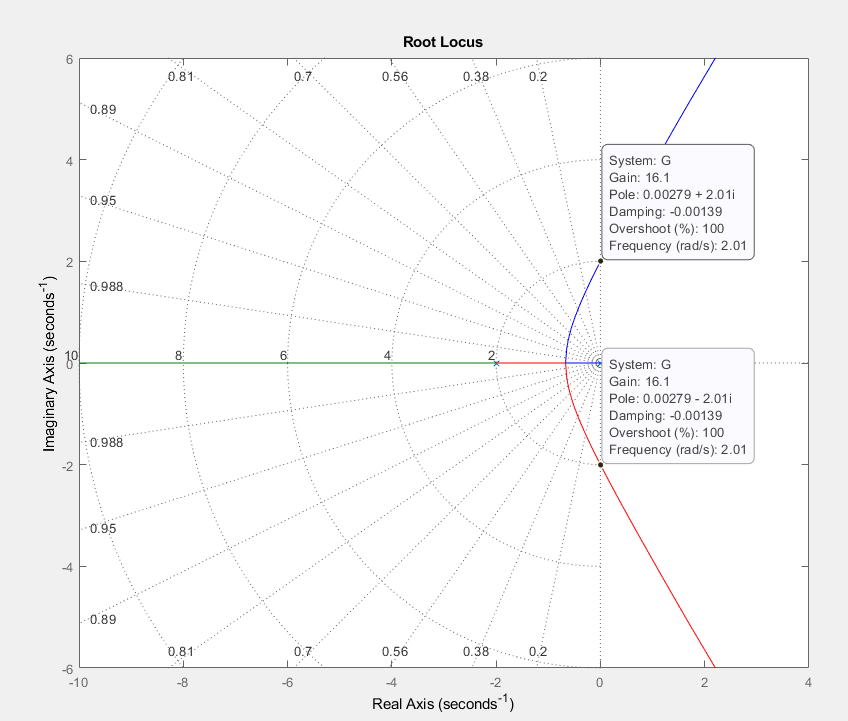

### Problem 5

*For each of Prelab Problems 2, 3, and 4, plot on one graph the pole locations for each case and write the corresponding value of gain, *$K$*, at each pole. *

**Answer:**

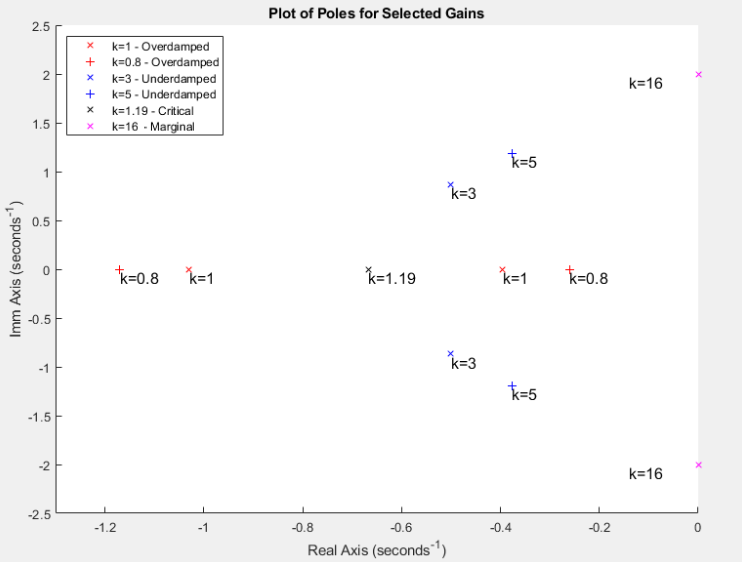

## Lab

### Problem 1

*Using Simulink, set up the negative feedback system of Prelab 1. Plot the step response of the system at each value of gain calculated to yield overdamped, underdamped, critically damped, and marginally stable responses.*

*For your Simulink, please provide a screenshot that **clearly** shows the system.*

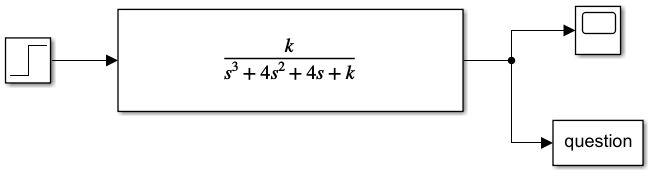

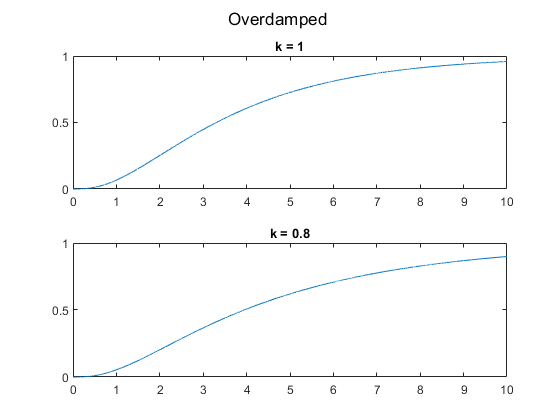

fc = 0;

% Overdamped
k_vals = [1, 0.8];
fc=fc+1; figure(fc);
for it=1:length(k_vals)
    k = k_vals(it);
    subplot(2,1,it);
    simOut = sim('ex6.slx','ReturnWorkspaceOutputs','on');
    plot(simOut.question.Time, simOut.question.Data);
    title("k = "+k);
end 
sgtitle("Overdamped ")

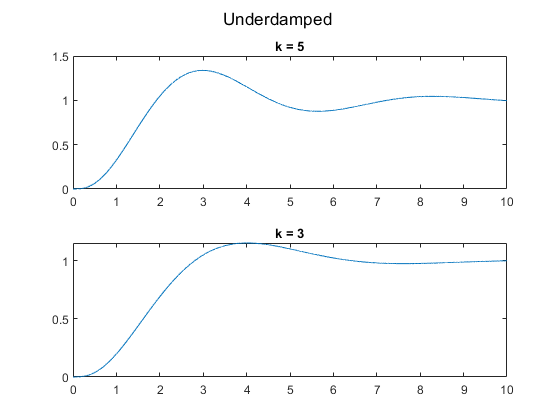


% Underdamped
k_vals = [5, 3];
fc=fc+1; figure(fc);
for it=1:length(k_vals)
    k = k_vals(it);
    subplot(2,1,it);
    simOut = sim('ex6.slx','ReturnWorkspaceOutputs','on');
    plot(simOut.question.Time, simOut.question.Data);
    title("k = "+k);
end 
sgtitle("Underdamped ")

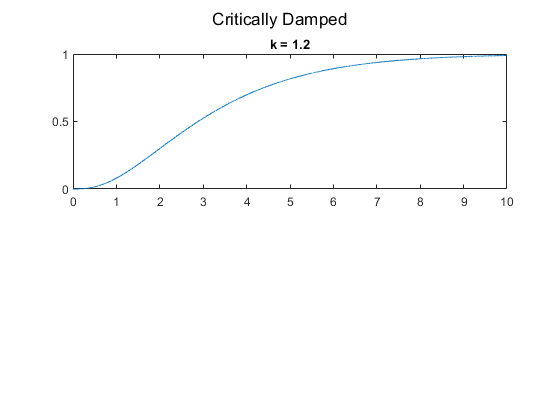


% Critically Damped
k_vals = [1.2];
fc=fc+1; figure(fc);
for it=1:length(k_vals)
    k = k_vals(it);
    subplot(2,1,it);
    simOut = sim('ex6.slx','ReturnWorkspaceOutputs','on');
    plot(simOut.question.Time, simOut.question.Data);
    title("k = "+k);
end 
sgtitle("Critically Damped")

### Problem 2

*Plot the step responses for two values of gain, *$K$*, above that calculated to yield marginal stability.*

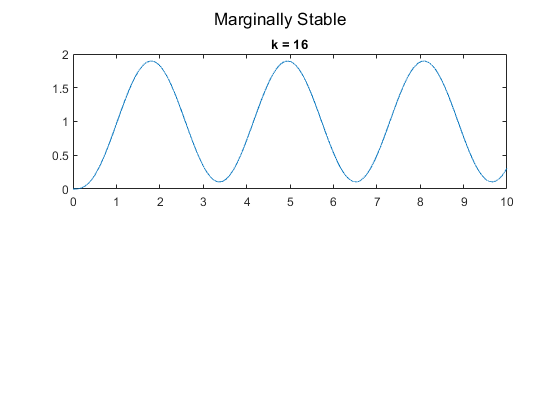

% Marginally Stable
k_vals = [16];
fc=fc+1; figure(fc);
for it=1:length(k_vals)
    k = k_vals(it);
    subplot(2,1,it);
    simOut = sim('ex6.slx','ReturnWorkspaceOutputs','on');
    plot(simOut.question.Time, simOut.question.Data);
    title("k = "+k);
end 
sgtitle("Marginally Stable")

### Problem 3

*At the output of the negative feedback system, cascade the transfer function *$G_1(s) = \frac{1}{s^2+4}$. *Set the gain, *$K$*, at a value below that calculated for matginal stability and plot the step response. Repeat for *$K$*calculated to yield marginal stability.*

*For your Simulink, please provide a screenshot that **clearly** shows the system.*

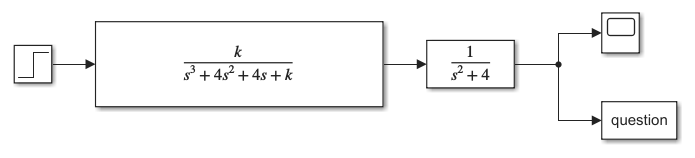

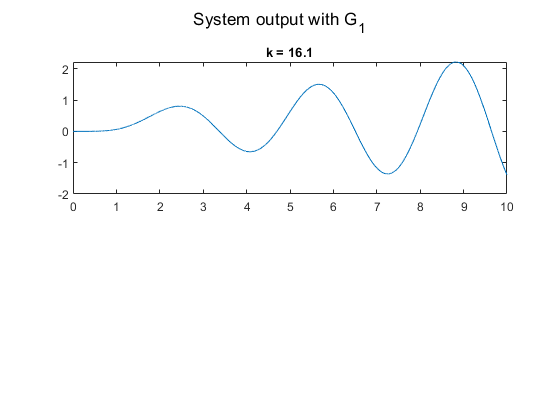

% Marginally Stable
k_vals = [16.1];
fc=fc+1; figure(fc);
for it=1:length(k_vals)
    k = k_vals(it);
    subplot(2,1,it);
    simOut = sim('ex6_3.slx','ReturnWorkspaceOutputs','on');
    plot(simOut.question.Time, simOut.question.Data);
    title("k = "+k);
end 
sgtitle("System output with G_1")

## Postlab

### Problem 1

*From your plots, discuss the conditions that lead to unstable responses.*

In order for a system to be stable the k must be such a value that keeps the poles in the left hand plane (or on the immaginary axis if the complex conjigant pole pair has a multiplicity of 1).

Passing the output of the marginally stable feedback system in problem 3 through 1/(s^2 + 4) made the system go unstable. If the system in problem 5 was combined into one transfer function, where k = 16.1, as estimated, the result would be:


$$\frac{16.1}{ s^5 + 4 s^4 +  8 s^3 + 32.1 s^2 + 16 s + 64.4}$$


The roots of this system were calculated through wolfrom alpha, and were found to be: -4, and $0 \pm j2$ with a multiplicity of 2. Whenever there is a complex congigate with a multiplicity greater than one on the immaginary axis, that leads the system to be unstable. Therefore, the results found in Problem 3 matches with theory. 

In the orginal system, used in Problem 2 and 3, as gain increased past 16 the system transistioned from marginally stable to unstable. This is because as gain increases, the complex conjigant pair cross into the right hand plane leading to instability. This could be verified using a Ruth Table by counting the number of sign changes in the right most column. Each sign change indicates another pole in the right hand plane, causing instability. For the example used above, it was found in the solved ruth table that any gain greater than 16 lead to the system going unstable as there would be a sign change in the table. However, in problem 4, the system was given a gain of exactly 16 to make it marginally stable, where there are poles on the $j\omega$ axis.

Other conditions that would lead to an unstable response include if the denominator of the system has coefficients of $s$ that do not have the same sign as all the other coefficients in the denominator or if there is a missing power of s (for instance $s^2 +4$). If either of these two conditions are true, the system is guaranteed to be unstable. 

### Problem 2

*Discuss the effect of Gain upon the nature of the step response of a closed-loop system.*

The gain of a system can have a large effect on its stabillity. By just varying the gain, this lab proved that a system could go from undamped, underdamped, critcally damped, overdamped, to unstable. It was seen in this lab, especially through Question 5 that as gain goes from 0 to infinity, the poles of the system were observed to move from their resting point at $k=0$ and move, assuming there is no poles, to infinity. Therefore, by modifying the gain, this lab showed that a system designer could move the poles to a desired location, if the system allows, to output the desired charecteristics of the system. A practical usecase could be to take an unstable open loop system, place it in a negative feedback loop and multiply it by a gain to manipulate its charecteristics.